% Write code that will:
%   Determine the reference threshold value from refImg.
%   Use this threshold to segment newImg without histogram matching. Save the results as newImgBW.
%   Match newImg's histogram to refImg's histogram. Then use the reference threshold to segment the histogram-matched crack image. Save the results as matchImgBW.
%Consider your results. Which segmentation is more accurate? Noisier? If you were detecting cracks to identify areas of a dam that need repair, would the histogram-matched segmentation be sufficient? Share your thoughts on the forums.

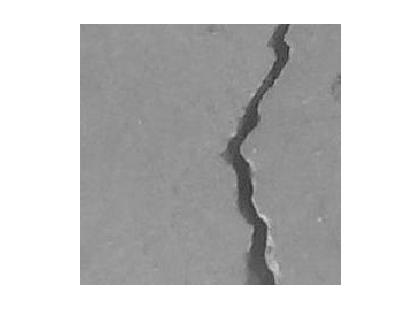

% Read in cracks and convert to grayscale
refImg = rgb2gray(imread("00004.jpg"));
newImg = rgb2gray(imread("00143.jpg"));
imshow(refImg)

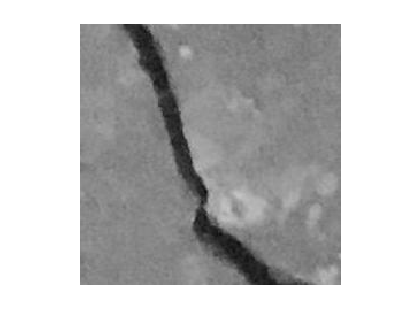

imshow(newImg)

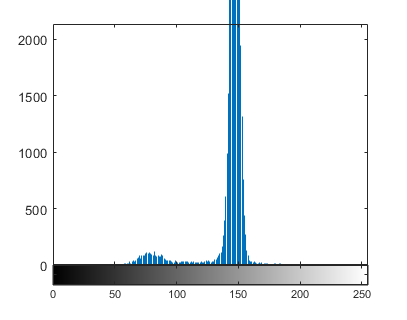

imhist(refImg);

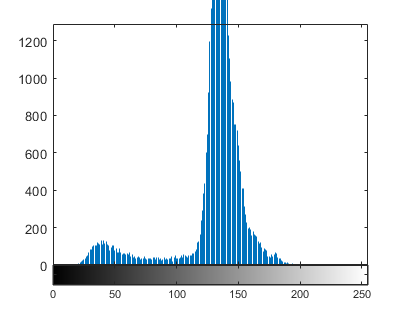

imhist(newImg);

refthresh = graythresh(refImg)

refthresh = 0.4510

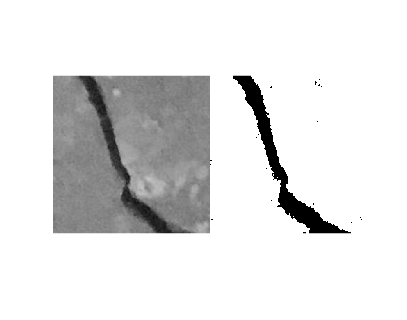

BW3 = imbinarize(newImg,refthresh);

montage({newImg,BW3})

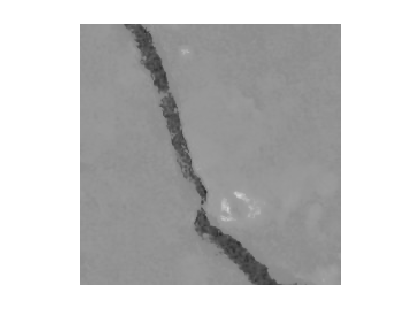


newImgBW = BW3;

histmatch = imhistmatch(im2uint8(newImg),im2uint8(refImg),256);
imshow(histmatch)

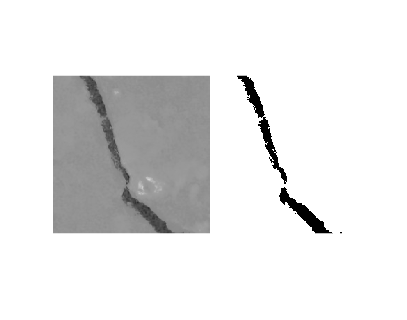

BW4 = imbinarize(histmatch,refthresh);
montage({histmatch,BW4})

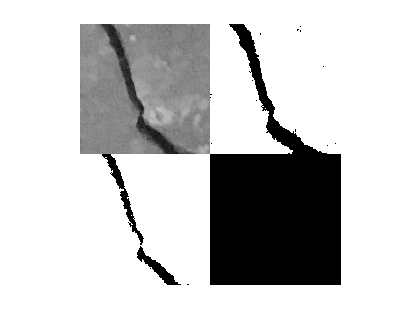

matchImgBW = BW4;

% Uncomment below to display Crack 00143 and both segmentations
 montage({newImg, newImgBW, matchImgBW})